# Cours 23.11.22

clear; clc; close;
% Interpolation polynomiale

## Rappels

% Points d'interpolation
x = [-2 -1 1 2]

x =     -2    -1     1     2


% Valeurs interpolées
y = [10 4 6 3]

y =     10     4     6     3



% On veut construire le polyonme de degré <= 3 qui
% passe exactement par ces points
V = vander(x)

V =     -8     4    -2     1
    -1     1    -1     1
     1     1     1     1
     8     4     2     1



% Ne fonctionne pas, y doit être en matrice colonne
% a = V\y
% Donc : 
y = y'

y =     10
     4
     6
     3


a = V\y

a =    -0.9167
    0.5000
    1.9167
    4.5000


% Dans a on trouve les coefficients du polynôme (plus grand au plus petit)

Meilleure méthode par Matlab :

% Sans construire la matrice V : on utilise polyfit
a = polyfit(x, y, 3)

a =    -0.9167    0.5000    1.9167    4.5000



% Pour évaluer le polynôme en 1 ou pusieurs points : on utilise polyval
polyval(a, -5)

ans = 122.0000

polyval(a, 5)

ans = -88.0000

polyval(a, 598)

ans = -195846640

## Dessin du polynôme et des points

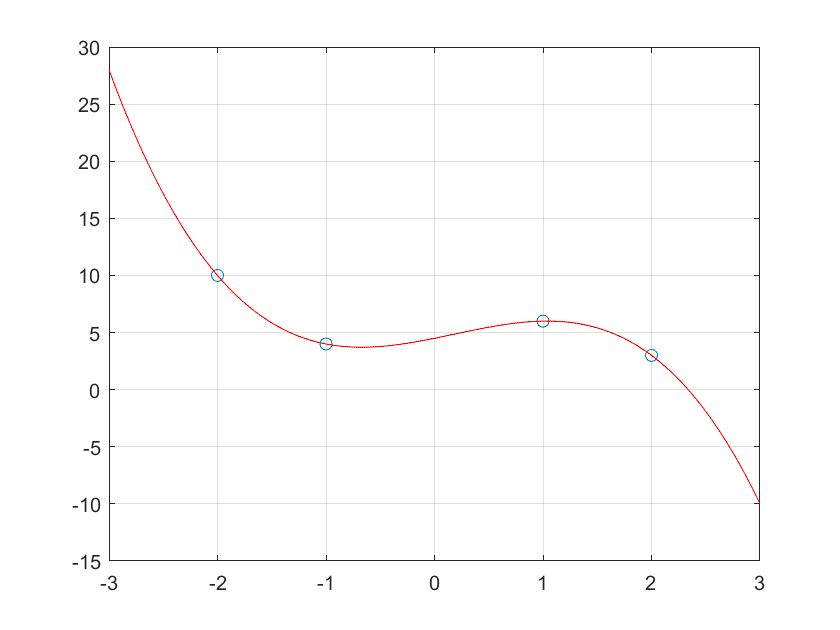

xx = linspace(-3, 3, 1e3);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');
grid on;
set(gcf,'Visible','on'); % Ouvre la fenêtre

# Deuxième exemple

clear;clc;close;
% On interpole la fonction sin(x)
% On prends 5 points x entre 0 et 2*pi
% Et les valeurs correspondantes (y) sont les valeurs du sin(x)

x = linspace(0, 2*pi, 5)

x =          0    1.5708    3.1416    4.7124    6.2832


y = sin(x)

y =          0    1.0000    0.0000   -1.0000   -0.0000



a = polyfit(x, y, 4)

a =    -0.0000    0.0860   -0.8106    1.6977    0.0000


## Dessin du polynôme et de la fonction sin(x)

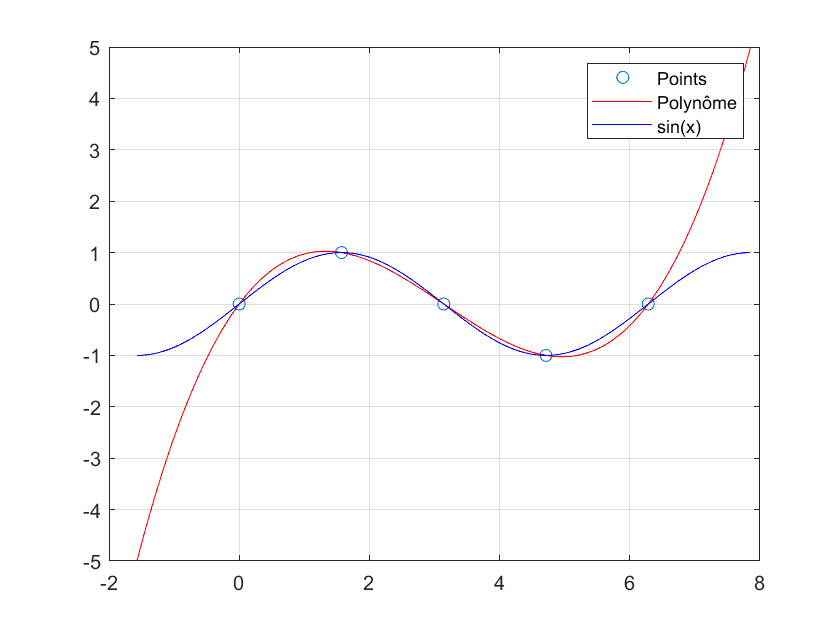

xx = linspace(-pi/2, 5*pi/2, 1e3);
p = polyval(a, xx);

plot(x, y, 'o', xx, p, 'r', xx, sin(xx), 'b');
grid on;
set(gcf,'Visible','on'); % Ouvre la fenêtre
legend('Points', 'Polynôme', 'sin(x)');

% Est-ce bon ?

## On augmente le nombre de points

clear;clc;close;
n = 10;
x = linspace(0, 2*pi, n)

x =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832


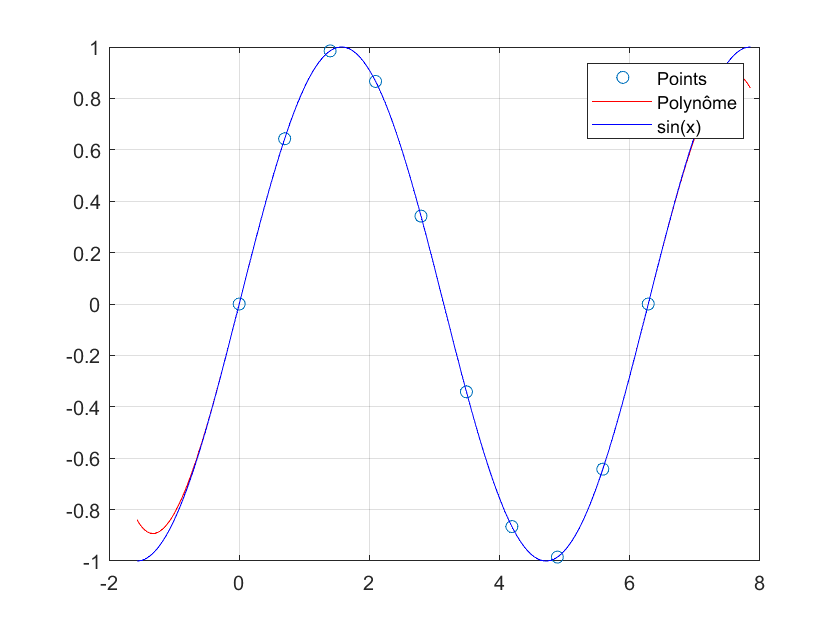

y = sin(x);
a = polyfit(x, y, n-1);
xx = linspace(-pi/2, 5*pi/2, 1e3);
p = polyval(a, xx);

plot(x, y, 'o', xx, p, 'r', xx, sin(xx), 'b');
grid on;
set(gcf,'Visible','on'); % Ouvre la fenêtre
legend('Points', 'Polynôme', 'sin(x)');

## Troisième exemple

On prends 10 points entre -1 et 1

La fonction à interpoler est la fonction 1/(1 + 25*x^2)

Dessin de f du polynôme et des points d'interpolation sur [-1, 1]

clear;clc;close;
n = 80;

fh = figure;
set(gcf,'Visible','on'); % Ouvre la fenêtre
fh.WindowState = 'maximized';

x = linspace(-1, 1, n);
y = 1./(1+25*(x.^2));
a = polyfit(x, y, n-1);

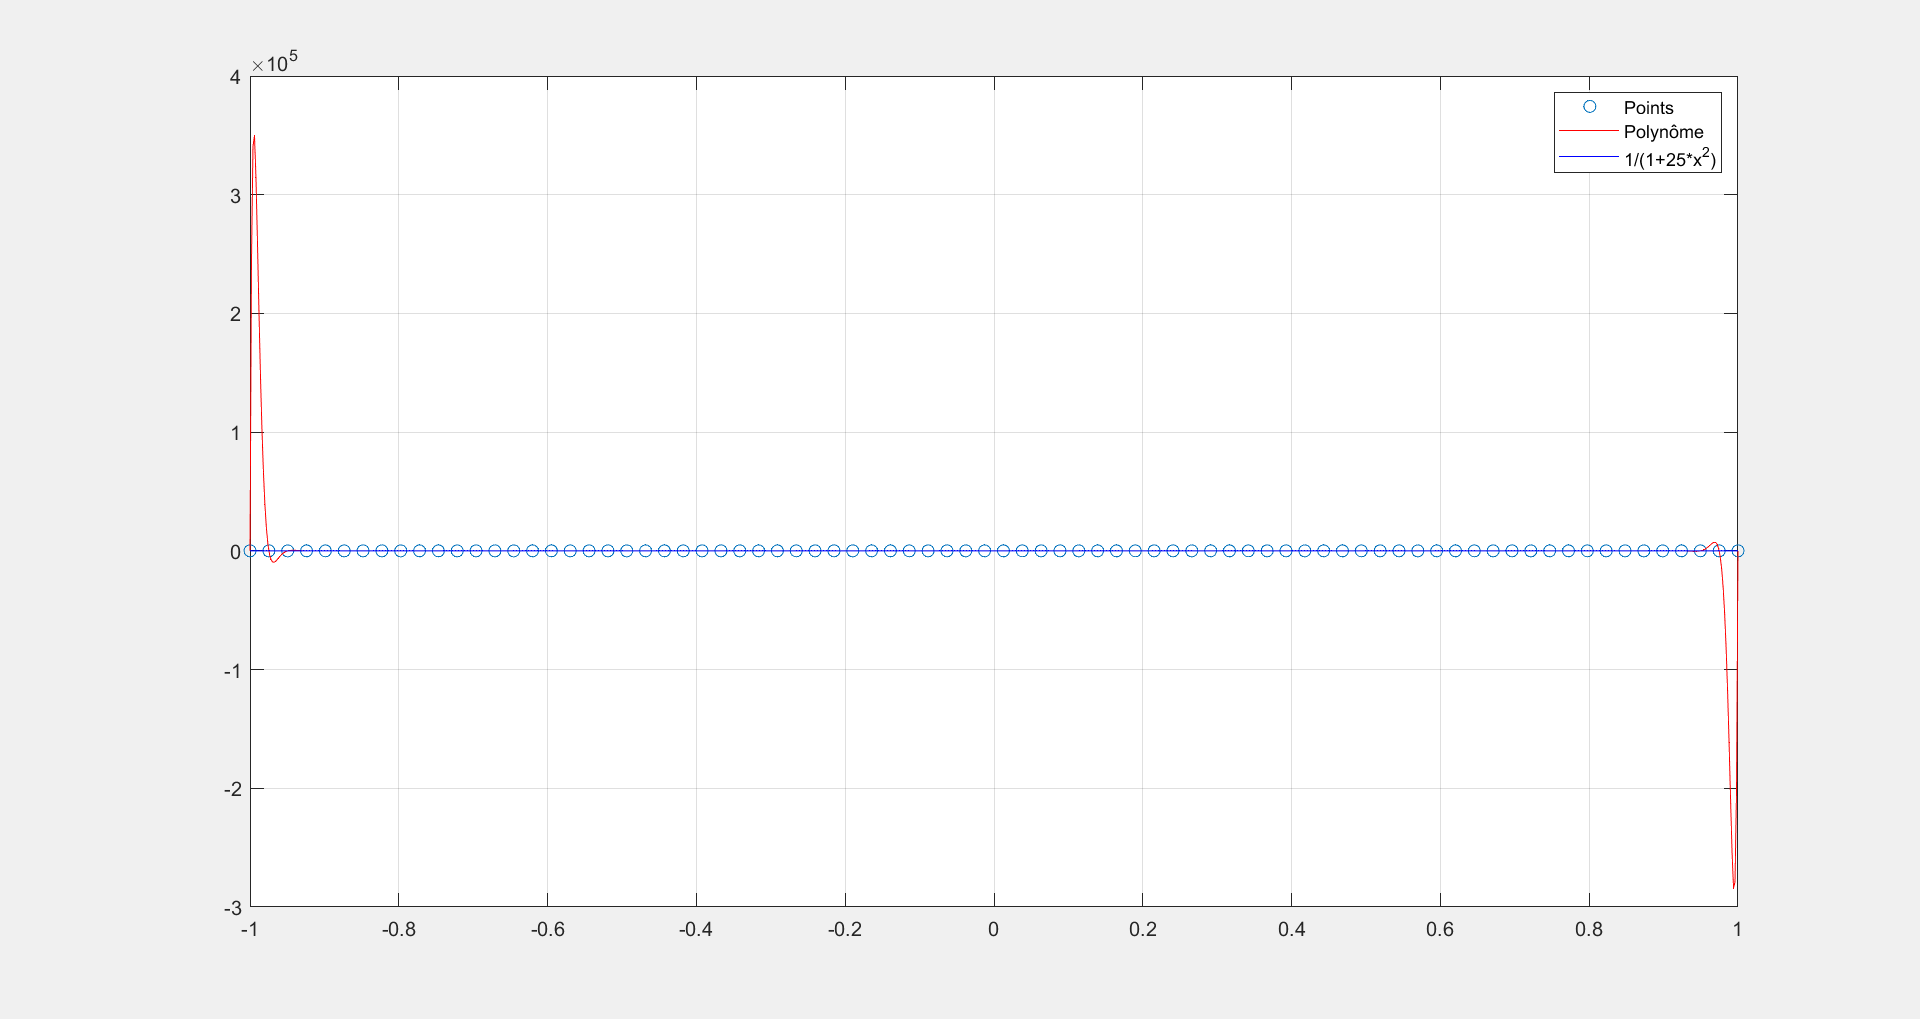

xx = linspace(-1, 1, 1e3);
p = polyval(a, xx);

plot(x, y, 'o', xx, p, 'r', xx, 1./(1+25*(xx.^2)), 'b');
grid on;
legend('Points', 'Polynôme', '1/(1+25*x^2)');

En augmentant le nombre de points, **la limite à gauche et à droite est toujours trop grande**. C'est à cause des points équidistants. On appelle **Phénomène de Runge**

% cond v
V = vander(x);
cond(V) % eps*cond = nbr chiffres significatis => cond trop grand. Non fiable

ans = 1.1877e+21

## Version avancée

On prends 10 points entre -1 et 1

La fonction à interpoler est la fonction 1/(1 + 25*x^2)

Dessin de f du polynôme et des points d'interpolation sur [-1, 1]

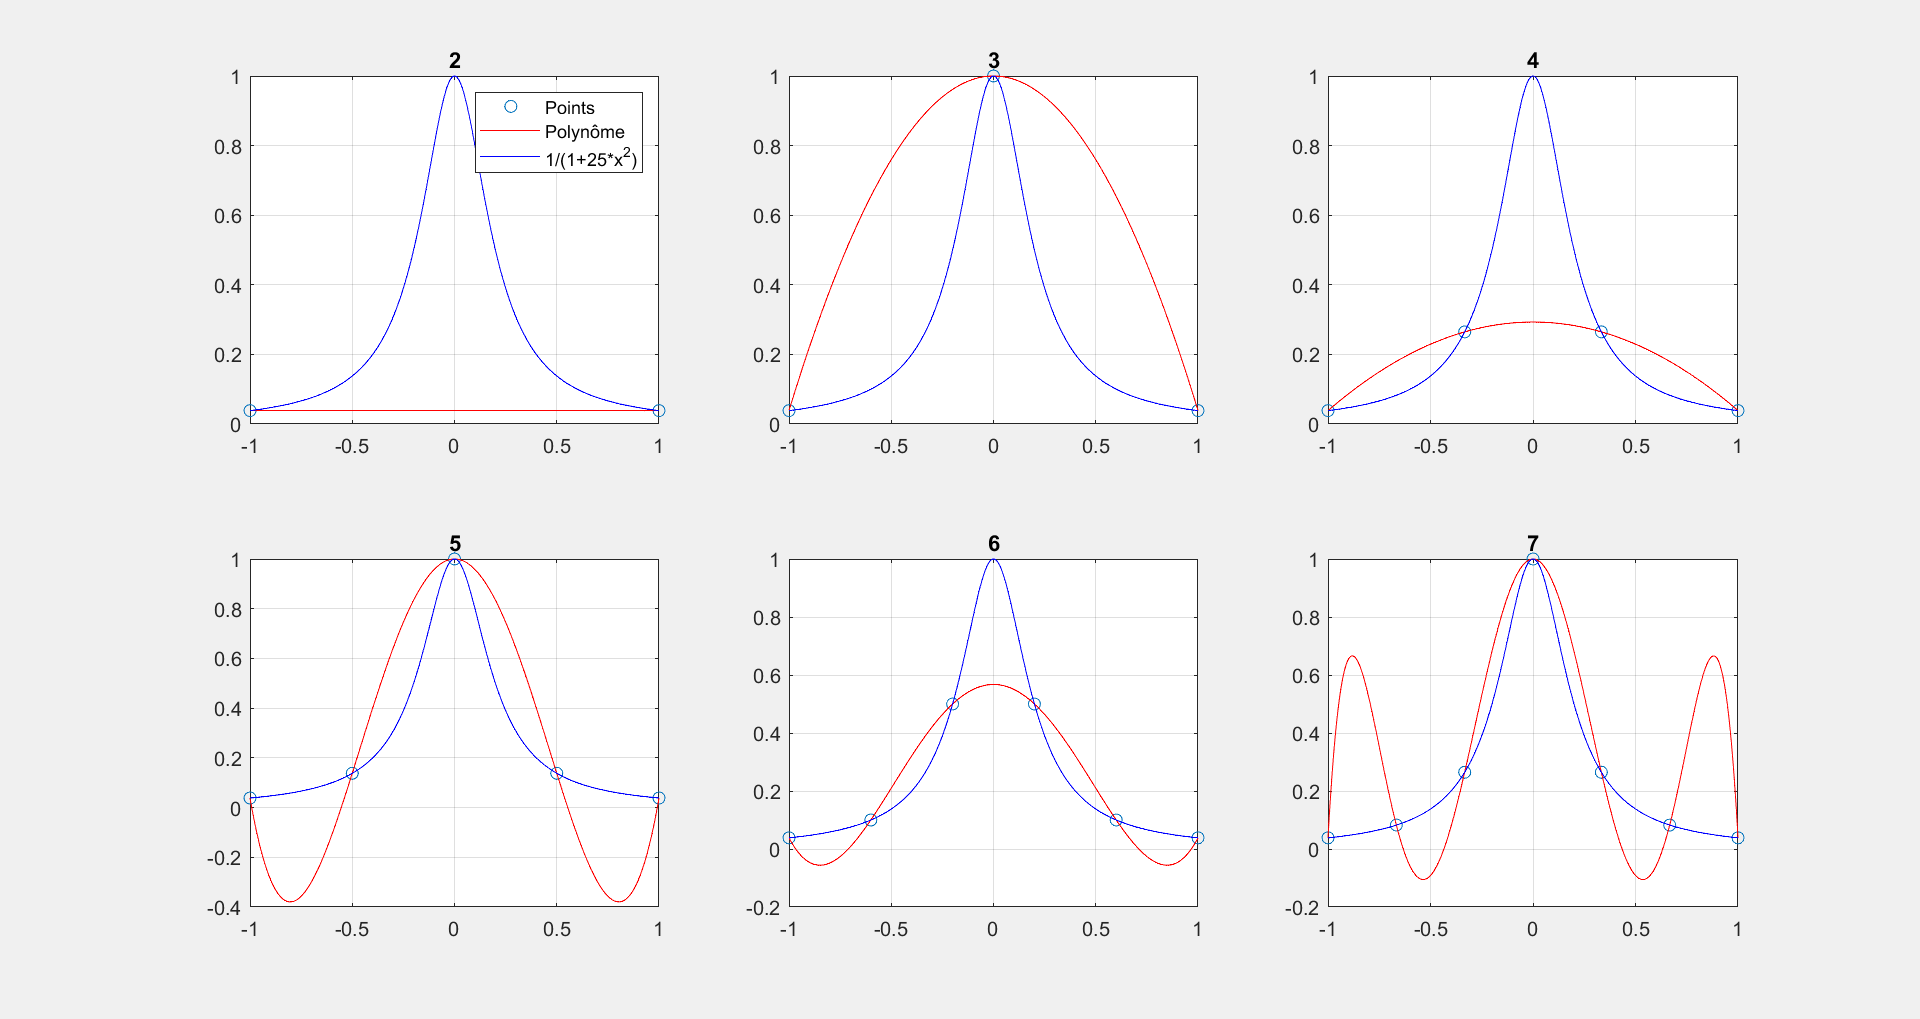

clear;clc;close;
n_start = 2;
n_c = 6;
c_c = min(n_c, 3);
r_c  = ceil(n_c/3);


fh = figure;
set(gcf,'Visible','on'); % Ouvre la fenêtre
fh.WindowState = 'maximized';

for n=1:n_c
    n_r = n+n_start-1;
    x = linspace(-1, 1, n_r);
    y = 1./(1+25*(x.^2));
    a = polyfit(x, y, n_r-1);
    xx = linspace(-1, 1, 1e3);
    p = polyval(a, xx);
    
    subplot(r_c, c_c, n);
    plot(x, y, 'o', xx, p, 'r', xx, 1./(1+25*(xx.^2)), 'b');
    grid on;
    if n == 1
        legend('Points', 'Polynôme', '1/(1+25*x^2)');
    end
    title(n_r);
end

## Interpolation linéaire par morceaux

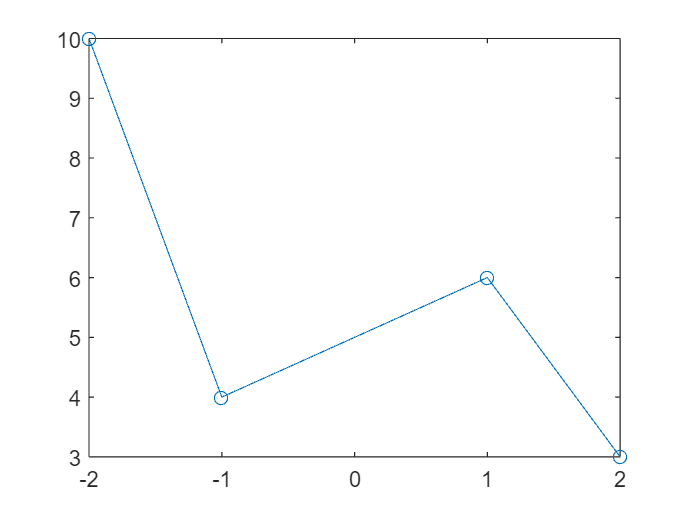

clear;clc;close;

x = [-2 -1 1 2];
y = [10 4 6 3];
plot(x, y, 'o-'); % Fini. Matlab fait tout seul

## Interpolation spline (essai hors cours) ex5.3

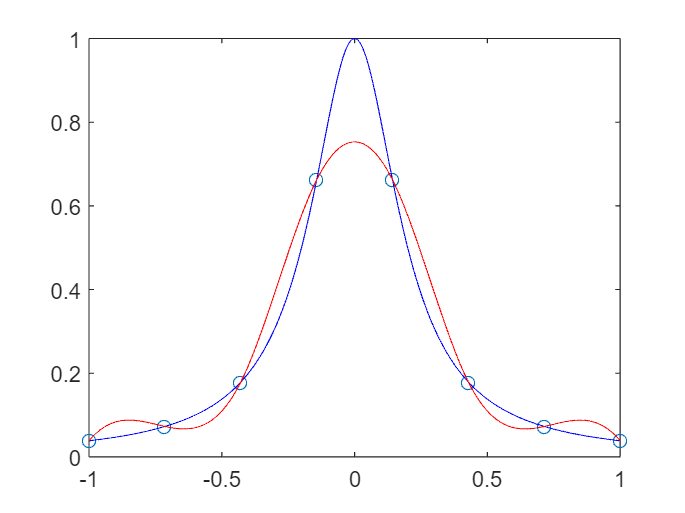


x = linspace(-1, 1, 8);
y = 1./(1+25*x.^2);

xx = linspace(-1, 1, 1e3);
pp = spline(x, y, xx);
yy = 1./(1+25*xx.^2);

plot(x, y, 'o', xx, yy, 'b', xx, pp, 'r');